% Assignment 1
% Brendan Horne
% Student ID: 12019269


% Question 1
syms v(x) x d c b a EI q L
v(x) = d*x^3 + c*x^2 + b*x + a

$$v(x) = d\,x^{3}+c\,x^{2}+b\,x+a$$

a1 = solve(v(0) == 0, a)

$$a1 = 0$$

v(x) = subs(v(x),a,a1)

$$v(x) = d\,x^{3}+c\,x^{2}+b\,x$$

b1 = solve(v(L) == 0, b)

$$b1 = -d\,L^{2}-c\,L$$

v(x) = subs(v(x),b,b1)

$$v(x) = d\,x^{3}+c\,x^{2}+\left(-d\,L^{2}-c\,L\right)\,x$$

d1v = diff(v(x),x)

$$d1v = -d\,L^{2}-c\,L+3\,d\,x^{2}+2\,c\,x$$

d2v = diff(d1v,x)

$$d2v = 2\,c+6\,d\,x$$

Ut = 0.5 * EI * int((d2v)^2,x,0,L) + int(q*x/L*v(x),x,0,L)

$$Ut = \frac{\mathrm{EI}\,\left(12\,L^{3}\,d^{2}+12\,L^{2}\,c\,d+4\,L\,c^{2}\right)}{2}-\frac{L^{3}\,q\,\left(5\,c+8\,L\,d\right)}{60}$$

dUtdd = diff(Ut,d)

$$dUtdd = \frac{\mathrm{EI}\,\left(24\,d\,L^{3}+12\,c\,L^{2}\right)}{2}-\frac{2\,L^{4}\,q}{15}$$

dUtdc = diff(Ut,c)

$$dUtdc = \frac{\mathrm{EI}\,\left(12\,d\,L^{2}+8\,c\,L\right)}{2}-\frac{L^{3}\,q}{12}$$

eqns = [dUtdd dUtdc];
S = solve(eqns,[d c]);
d = S.d

$$d = \frac{L\,q}{360\,\mathrm{EI}}$$

c = S.c

$$c = \frac{L^{2}\,q}{60\,\mathrm{EI}}$$

b = -d*L^2 - c*L

$$b = -\frac{7\,L^{3}\,q}{360\,\mathrm{EI}}$$

v(x) = subs(v(x))

$$v(x) = \frac{L\,q\,x^{3}}{360\,\mathrm{EI}}-\frac{7\,L^{3}\,q\,x}{360\,\mathrm{EI}}+\frac{L^{2}\,q\,x^{2}}{60\,\mathrm{EI}}$$

% Let q = 5m, EI = 200,000Nm*m and L = 2m
v(x) = subs(v(x), [q EI L],[5,200000 2])

$$v(x) = \frac{x^{3}}{7200000}+\frac{x^{2}}{600000}-\frac{7\,x}{1800000}$$

d1v = diff(v(x))

$$d1v = \frac{x^{2}}{2400000}+\frac{x}{300000}-\frac{7}{1800000}$$

x_max = solve(d1v,x)

$$x\_max = \left(\begin{array}{c} -\frac{2\,\sqrt{3}\,\sqrt{19}}{3}-4\\ \frac{2\,\sqrt{3}\,\sqrt{19}}{3}-4 \end{array}\right)$$

for i = 1:length(x_max)
    if x_max(i) >= 0 && x_max(i) <= 2
        x1 = x_max(i);
    end
end
x1 = double(x1)

x1 =    1.033222956847166

q1 = double(v(x1))

q1 =     -2.085643029665245e-06

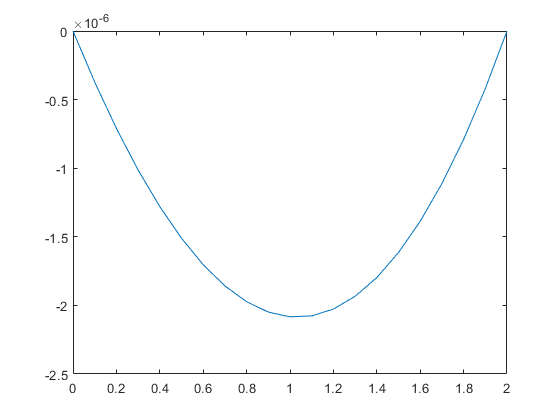

x = 0:0.1:2;
plot(x, v(x))

% Comments:
% Very close to the true solution
clearvars


% Question 2
syms v(x) x f e d c b a EI q L
v(x) = f*x^5 + e*x^4 + d*x^3 + c*x^2 + b*x + a

$$v(x) = f\,x^{5}+e\,x^{4}+d\,x^{3}+c\,x^{2}+b\,x+a$$

a1 = solve(v(0) == 0, a)

$$a1 = 0$$

v(x) = subs(v(x),a,a1)

$$v(x) = f\,x^{5}+e\,x^{4}+d\,x^{3}+c\,x^{2}+b\,x$$

b1 = solve(v(L) == 0, b)

$$b1 = -f\,L^{4}-e\,L^{3}-d\,L^{2}-c\,L$$

v(x) = subs(v(x),b,b1)

$$v(x) = f\,x^{5}+e\,x^{4}+d\,x^{3}+c\,x^{2}+\left(-f\,L^{4}-e\,L^{3}-d\,L^{2}-c\,L\right)\,x$$

d1v = diff(v(x),x)

$$d1v = -f\,L^{4}-e\,L^{3}-d\,L^{2}-c\,L+5\,f\,x^{4}+4\,e\,x^{3}+3\,d\,x^{2}+2\,c\,x$$

d2v = diff(d1v,x)

$$d2v = 20\,f\,x^{3}+12\,e\,x^{2}+6\,d\,x+2\,c$$

Ut = 0.5 * EI * int((d2v)^2,x,0,L) + int(q*x/L*v(x),x,0,L)

$$Ut = \frac{\mathrm{EI}\,\left(4\,L\,c^{2}+L^{3}\,\left(12\,d^{2}+16\,c\,e\right)+L^{5}\,\left(\frac{144\,e^{2}}{5}+48\,d\,f\right)+L^{4}\,\left(20\,c\,f+36\,d\,e\right)+\frac{400\,L^{7}\,f^{2}}{7}+12\,L^{2}\,c\,d+80\,L^{6}\,e\,f\right)}{2}-\frac{L^{3}\,q\,\left(80\,f\,L^{3}+70\,e\,L^{2}+56\,d\,L+35\,c\right)}{420}$$

dUtdf = diff(Ut,f)

$$dUtdf = \frac{\mathrm{EI}\,\left(\frac{800\,f\,L^{7}}{7}+80\,e\,L^{6}+48\,d\,L^{5}+20\,c\,L^{4}\right)}{2}-\frac{4\,L^{6}\,q}{21}$$

dUtde = diff(Ut,e)

$$dUtde = \frac{\mathrm{EI}\,\left(80\,f\,L^{6}+\frac{288\,e\,L^{5}}{5}+36\,d\,L^{4}+16\,c\,L^{3}\right)}{2}-\frac{L^{5}\,q}{6}$$

dUtdd = diff(Ut,d)

$$dUtdd = \frac{\mathrm{EI}\,\left(48\,f\,L^{5}+36\,e\,L^{4}+24\,d\,L^{3}+12\,c\,L^{2}\right)}{2}-\frac{2\,L^{4}\,q}{15}$$

dUtdc = diff(Ut,c)

$$dUtdc = \frac{\mathrm{EI}\,\left(20\,f\,L^{4}+16\,e\,L^{3}+12\,d\,L^{2}+8\,c\,L\right)}{2}-\frac{L^{3}\,q}{12}$$

eqns =  [dUtdf dUtde dUtdd dUtdc];
S = solve(eqns,[f e d c]);
f = S.f

$$f = -\frac{q}{120\,\mathrm{EI}\,L}$$

e = S.e

$$e = 0$$

d = S.d

$$d = \frac{L\,q}{36\,\mathrm{EI}}$$

c = S.c

$$c = 0$$

b = subs(b1)

$$b = -\frac{7\,L^{3}\,q}{360\,\mathrm{EI}}$$

v(x) = subs(v(x))

$$v(x) = \frac{L\,q\,x^{3}}{36\,\mathrm{EI}}-\frac{7\,L^{3}\,q\,x}{360\,\mathrm{EI}}-\frac{q\,x^{5}}{120\,\mathrm{EI}\,L}$$

% Let q = 5m, EI = 200,000Nm*m and L = 2m
v(x) = subs(v(x), [q EI L],[5,200000 2])

$$v(x) = -\frac{x^{5}}{9600000}+\frac{x^{3}}{720000}-\frac{7\,x}{1800000}$$

d1v = diff(v(x))

$$d1v = -\frac{x^{4}}{1920000}+\frac{x^{2}}{240000}-\frac{7}{1800000}$$

x_max = solve(d1v,x)

$$x\_max = \left(\begin{array}{c} \sqrt{4-\frac{8\,\sqrt{30}}{15}}\\ \sqrt{\frac{8\,\sqrt{30}}{15}+4}\\ -\sqrt{4-\frac{8\,\sqrt{30}}{15}}\\ -\sqrt{\frac{8\,\sqrt{30}}{15}+4} \end{array}\right)$$

for i = 1:length(x_max)
    if x_max(i) >= 0 && x_max(i) <= 2
        x2 = x_max(i);
    end
end
x2 = double(x2)

x2 =    1.038659244718456

q2 = double(v(x2))

q2 =     -2.608873692767745e-06

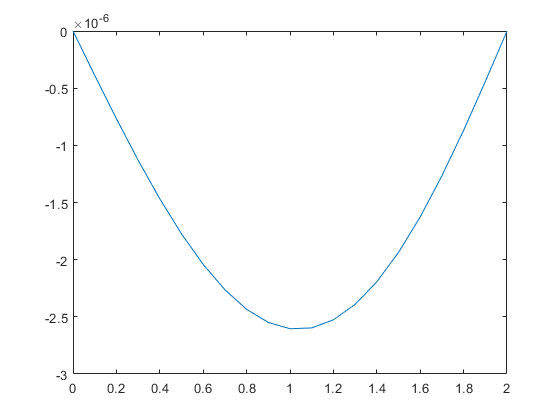

x = 0:0.1:2;
plot(x, v(x))

% Comments: true solution
clearvars


% Question 3
syms v(x) x L T t EI m;
v(x) = (3*x^2*L-x^3)*cos(((2*pi)/T)*t)

$$v(x) = \cos\left(\frac{2\,\pi \,t}{T}\right)\,\left(3\,L\,x^{2}-x^{3}\right)$$

d1v = diff(v(x),x)

$$d1v = \cos\left(\frac{2\,\pi \,t}{T}\right)\,\left(6\,L\,x-3\,x^{2}\right)$$

d2v = diff(d1v,x)

$$d2v = \cos\left(\frac{2\,\pi \,t}{T}\right)\,\left(6\,L-6\,x\right)$$

d2v = subs(d2v,t,0)

$$d2v = 6\,L-6\,x$$

Smax = int(0.5 * EI * d2v^2,x,0,L)

$$Smax = 6\,\mathrm{EI}\,L^{3}$$

vk = subs(v,x,L)

$$vk(x) = 2\,L^{3}\,\cos\left(\frac{2\,\pi \,t}{T}\right)$$

vk = subs(vk,t,0)

$$vk(x) = 2\,L^{3}$$

Kmax = 0.5 * m * (((2*pi)/T)*vk)^2

$$Kmax(x) = \frac{8\,L^{6}\,m\,\pi^{2}}{T^{2}}$$

eqn = Smax == Kmax

$$eqn(x) = 6\,\mathrm{EI}\,L^{3}=\frac{8\,L^{6}\,m\,\pi^{2}}{T^{2}}$$

T = solve(eqn,T)

$$T = \left(\begin{array}{c} -\frac{\pi \,\sqrt{\frac{16\,L^{3}\,m}{3\,\mathrm{EI}}}}{2}\\ \frac{\pi \,\sqrt{\frac{16\,L^{3}\,m}{3\,\mathrm{EI}}}}{2} \end{array}\right)$$

% Let m = 100kg, EI = 200,000, L = 1;
m = 100;
EI = 200000;
L = 1;
T = subs(T(2));
double(T)

ans =    0.081115573519472

% Let t = 0;
t = 0;
v(x) = subs(v(x))

$$v(x) = 3\,x^{2}-x^{3}$$

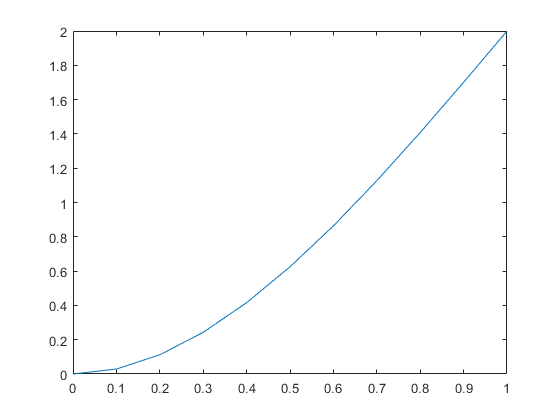

x = 0:0.1:1;
plot(x, v(x))

clearvars


% Question 4
syms theta L k P lambda
TPE = 1/2*k*(1/2*L*theta)^2 - P*(1/2*L*theta^2)==0

$$TPE = \frac{L^{2}\,k\,\theta^{2}}{8}-\frac{L\,P\,\theta^{2}}{2}=0$$

TPE = TPE / theta^2

$$TPE = \frac{\frac{L^{2}\,k\,\theta^{2}}{8}-\frac{L\,P\,\theta^{2}}{2}}{\theta^{2}}=0$$

TPE = expand(TPE)

$$TPE = \frac{L^{2}\,k}{8}-\frac{L\,P}{2}=0$$

P = solve(TPE,P)

$$P = \frac{L\,k}{4}$$


clearvars


% Question 5
syms theta L k P lambda
TPE = 1/2*k*(1/2*L*theta)^2 - P*(1/2*L*theta^2)==0

$$TPE = \frac{L^{2}\,k\,\theta^{2}}{8}-\frac{L\,P\,\theta^{2}}{2}=0$$

TPE = TPE / theta^2

$$TPE = \frac{\frac{L^{2}\,k\,\theta^{2}}{8}-\frac{L\,P\,\theta^{2}}{2}}{\theta^{2}}=0$$

TPE = expand(TPE)

$$TPE = \frac{L^{2}\,k}{8}-\frac{L\,P}{2}=0$$

TPE = TPE / k

$$TPE = \frac{\frac{L^{2}\,k}{8}-\frac{L\,P}{2}}{k}=0$$

TPE = expand(TPE)

$$TPE = \frac{L^{2}}{8}-\frac{L\,P}{2\,k}=0$$

TPE = subs(TPE, P/k,lambda)

$$TPE = \frac{L^{2}}{8}-\frac{L\,\lambda }{2}=0$$

A = lhs(TPE)

$$A = \frac{L^{2}}{8}-\frac{L\,\lambda }{2}$$

A = eig(A)

$$A = \frac{L^{2}}{8}-\frac{L\,\lambda }{2}$$

lambda = solve(A,lambda)

$$lambda = \frac{L}{4}$$

clear syms
syms L k P
eqn = P/k == lambda

$$eqn = \frac{P}{k}=\frac{L}{4}$$

P = solve(eqn,P)

$$P = \frac{L\,k}{4}$$